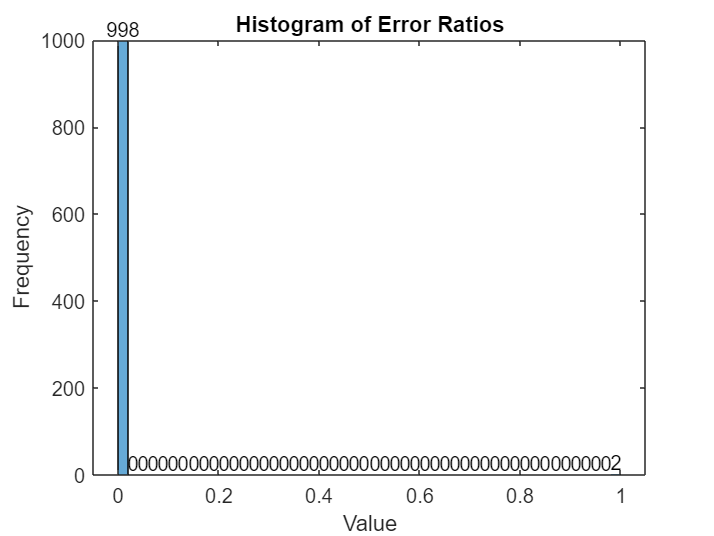

% Define the file name
filename_o = "";
filename_w = "";

% Open the file for reading
fileID_o = fopen(filename_o, 'r');
fileID_w = fopen(filename_w, 'r');

% Initialize a cell array to store the lines
lines_o = cell(1000, 1);
lines_w = cell(1000, 1);

% Use a for loop to read and fill the cell array
for lineIndex = 1:1000
    line = fgetl(fileID_o);
    lines_o{lineIndex} = line;
end

for lineIndex = 1:1000
    line = fgetl(fileID_w);
    lines_w{lineIndex} = line;
end

% Close the file
fclose(fileID_o);
fclose(fileID_w);

decimalLines_o = cell(1000,1);
decimalLines_w = cell(1000,1);

for i = 1:1000
        hexValue = uint32(hex2dec(lines_o{i}(3:10)));
        singleValue = typecast(hexValue, 'single');
        decimalLines_o{i} = singleValue;

end

for i = 1:1000
        hexValue = uint32(hex2dec(lines_w{i}(3:10)));
        singleValue = typecast(hexValue, 'single');
        decimalLines_w{i} = singleValue;
end

difference_cell = cell(1000, 1);

for i = 1:1000
    if decimalLines_w {i} == decimalLines_o {i}
        difference = 0;
    else
        difference = abs(decimalLines_o{i} - decimalLines_w {i});
    end
 difference_cell{i} = double(difference);
end

percentages_cell = cell(1000,1);

for i = 1:1000
    percentage = difference_cell{i} / decimalLines_o {i};
    percentages_cell{i} = abs(percentage);
end
    


numericArray_2 = cell2mat(percentages_cell);

% Calculate the histogram data
[h, edges] = histcounts(numericArray_2);

% Create the histogram plot
histogram(numericArray_2);
title('Histogram of Error Ratios');
xlabel('Value');
ylabel('Frequency');

% Add text annotations for each bin (showing the count)
for i = 1:numel(h)
    text(edges(i) + (edges(i+1) - edges(i)) / 2, h(i), num2str(h(i)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end